# El conjunto de Mandelbrot y Julia

## Set de Mandelbrot

col = 20;
c = 0;
res = 1000;
W = f_mandelbrot(res,col,c);
figure,
imagesc(W),
colorbar
colormap(map)



## Set de Julia

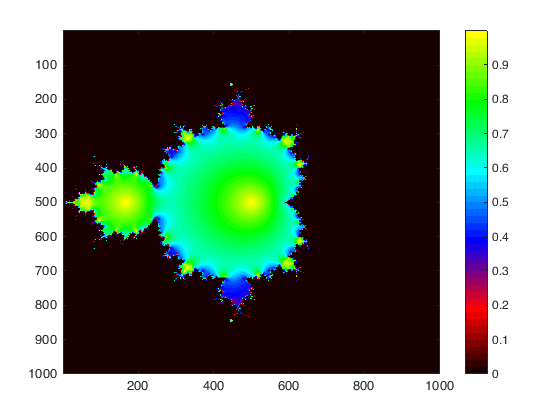

col = 5;
cR = 0.3;

cI = 0.83i;
n = 5;
res = 1000;
W = f_julia_set(res,col,n,cR+cI);
figure,
imagesc(W),
colorbar
colormap(map)


## Color Map

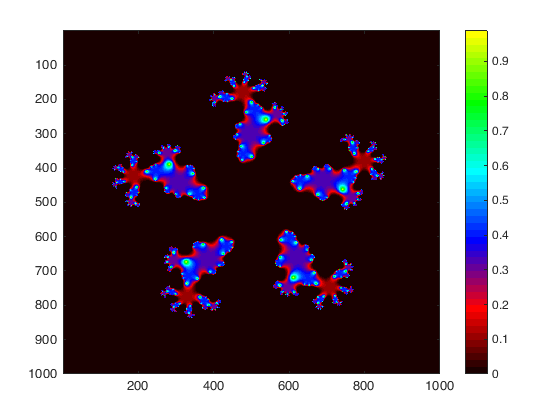

map = [];
% negro ->rojo
n = 10;
for i=1:n
    map = [map;[i/n,0,0]];

end
% rojo -> azul
for i=1:n
    map = [map;[1-i/n,0,i/n]];
end
% azul -> aguamarina
for i=1:n
    map = [map;[0,i/n,1]];
end

% aguamarina->verde
for i=1:n
    map = [map;[0,1,1-i/n]];
end
% verde->amarillo
for i=1:n
    map = [map;[i/n,1,0]];
end
